% to run this script there are a few pre-requisite .m files and datafiles
% that need to be downloaded and placed into the same directory as this
% code. please refer to the README.dat file given in the GITHUB repository.
% Thanks.

clc;
    clear all;
    close all;

        % 1 == ON, 0 == OFF
    perform_phase_correction = 1

perform_phase_correction = 1

%%% DATA LOADING - ALL INDIVIDUAL ECHOES %%%

    pathway = 'C:\Users\985080\OneDrive - Swansea University\Desktop\raw data (MBEM)\';
    filename_start = 'dy010';
    
    start_index = 278;
    end_index = 477;

    N_grads = (end_index - start_index)+1; %gradient variation per loop
    N_B1 = 41;
    N_grad = 49;

    full_data_array = zeros([N_B1, N_grads]);
    long_cat_data = [];


%%% DEFINING SYSTEM PARAMETERS %%%
   
    %%% currents defined
    I_list_echo = linspace(0.264030, 0.284030, 41);
    I_list_grad = linspace(-11.2019, 11.2019, 49);

    %%% variables to change %%%
    selection_threshold = 0.6;

    %%% fixed constants %%%
    field_int = 111.8297e-4; % [Tm A^-1] for B1 solenoid
    m = 4.9976e-27; % mass of helium-3
    delta_I = 0.02; %this is actually I_max ????? 
    gamma_bar = 32.4340921e6; % s^-1 T^-1 rad
    gamma = gamma_bar * (2*pi); % s^-1 T^-1
    h = 6.626e-34;

    FOV = 2.5e-3;
    N_grad = 49;
    N_lambda = 41; 
    N_loops = 4;

    central_grad_index = 25; % for selecting central echo scan
    central_echo_index = 21; % for selecting central gradient scan

    %%% array definitions %%%
        %% lambda defined
    delta_lambda = ( field_int * delta_I * (m/h) * (gamma/(2*pi)) )^(-1);
    lambda_list = linspace(-20, 20, N_lambda) * (delta_lambda);
    v_list = h ./ (m*lambda_list);
    k1_list = gamma_bar * (m * field_int .* I_list_echo)/(h);
        %% gradient defined
    delta_k = 1/FOV;
    k_space_gradients = linspace(-(N_grads-1)/2, ((N_grads-1)/2), N_grads) .* delta_k;
    x_axis = linspace(-FOV/2, FOV/2, N_grad);


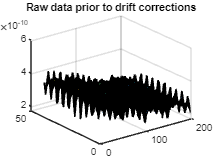

%%% SEQUENTIAL LOADING OF DY010XXX.dat ECHOES %%%

    j=1;
    for i=(start_index:1:end_index)
        filename_end = num2str(i);
        file_name = strcat(pathway, filename_start, filename_end);
        %addpath('scripts');
        addpath('prereq_echo_reader');
        [Iscan,counts,datavec,lam,spec_lamX] = read_current_scan_h2_new1([file_name,'.dat'],1,1,1,0);
        full_data_array(:, j) = counts;
        long_cat_data = [long_cat_data, counts];
        j=j+1;
    end
    
        figure();
            surf(full_data_array);
            title('Raw data prior to drift corrections');

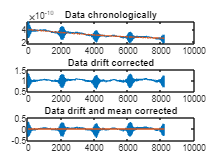

%%% DRIFT CORRECTION OF CHRONOLOGICAL DATA %%%

    full_data = long_cat_data;
    
    x=1:length(full_data);
    [a, b]=polyfit(x, full_data, 2);
    fitmag=a(3)+a(2)*x+a(1)*x.^2;

    subplot(3,1,1)
        % illustrates need for drift correction
            plot(long_cat_data)
            hold on; plot(fitmag); hold off;
            title('Data chronologically')

    subplot(3,1,2)
        % plot after drift correction
            full_data = (full_data)./(fitmag);
            plot(full_data);
            title('Data drift corrected')
    
    subplot(3,1,3)
        % plot after mean correction
            full_data = full_data - mean(full_data);
            plot(full_data); 
            hold on; plot(fitmag); hold off
            title('Data drift and mean corrected')

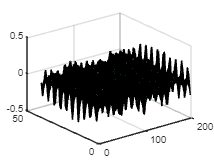

            
    full_data_array = reshape(full_data, [41, 200]);
    figure()
        surf(full_data_array)

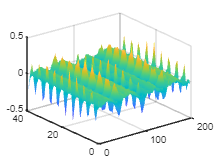

%%% APPLYING PHASE CORRECTION via FT-SHIFT THEOREM
% note this version omits FFTSHIFTS

    if perform_phase_correction == 1
            % loads phase corrections from "checking_echo_run_echoes.mlx" 
            % THIS SCRIPT IS IN THE 'ALL SCRIPTS' FOLDER
        phase_corrections = load('phase correction shifts.txt');
    
        k1_shifts = (-gamma_bar * (m * field_int .* phase_corrections))/(h); 
        lambda_list_phase_corr = [(0:1:19)*delta_lambda -max(lambda_list)+(0:1:19)*delta_lambda];

        phase_corrected_array = [];
        for i=1:200
            dummy_fft = fft(full_data_array(1:end-1,i));
            phase_corrected_array(:,i) = ifft( exp(1i*2*pi*k1_shifts(i).*lambda_list_phase_corr') .* dummy_fft);
        end
    
        full_data_array = phase_corrected_array;
    
        figure()
            surf(real(phase_corrected_array))
            shading interp
%         figure()
%             surf(imag(phase_corrected_array))
%             shading interp
%         figure()
%             surf(abs(phase_corrected_array))
%             shading interp
    end

%%% RE-ARRANGE DATA INTO RECIPROCAL SPACE ARRAY %%%
    if perform_phase_correction == 1
        N_B1 = 40;
    else
        N_B1 = 41;
    end

    reshaped_data = reshape(full_data_array, [N_B1, N_grads]);
    if perform_phase_correction == 1
        new_array = zeros(40, 49, 4);
    else
        new_array = zeros(41,49, 4);
    end

    % seg_x have same polarity measurements
    % LHS and RHS are flipped polarities of current ramping

    for i=1:N_B1
        seg1 = [ reshaped_data(i, 1:25)' , reshaped_data(i, 101:125)' ];
        seg2 = [ reshaped_data(i, 26:50)', reshaped_data(i, 126:150)' ];
        seg3 = [ reshaped_data(i, 51:75)', reshaped_data(i, 151:175)' ];
        seg4 = [ reshaped_data(i, 76:100)', reshaped_data(i, 176:200)' ];

        RHS = [seg4, flipud(seg3)];
        LHS = [seg2, flipud(seg1)];
        RHS(1, :) = []; % removal of double 0 current measurement

        new_array(i, :, :) = [ LHS', fliplr(RHS') ]';
    end

        %%% PLOTTING OF ALL 4 INDIVIDUAL LOOPS %%% 

    mean_data_array = mean(new_array, 3);
%     surf(real(mean_data_array))
%     surf(imag(mean_data_array))
%     surf(abs(mean_data_array))
    

%%% ANALYSIS OF DATA ARRAY %%%

    mean_data_array = mean(new_array, 3); % mean of 4 loops
    mean_data_array = mean_data_array - mean(mean(mean_data_array)); %normalise

    std_data_array = std(new_array, 0, 3);
    error_data_array = std_data_array ./ sqrt(4); % error from 4 loops


%%% REMOVAL OF DATA POINTS (COUNTERING WINDOWING)

    lambda_list(end) = [];
    x_axis(end) = [];
    mean_data_array(:,end) = [];
    new_array(:,end,:) = [];
    
    I_list_echo(end) = [];
    I_list_grad(end) = [];

    if perform_phase_correction == 0
        mean_data_array(end,:) = []; % already done in phase correction part
        std_data_array(end, :) = [];
        new_array(end,:,:) = [] ;
    end


%%% SPIN-ECHO SIGNAL WITH ERROR %%%
    
    plot_individual_loops = 1 %1 for plotting, 0 for omitted plots

plot_individual_loops = 1

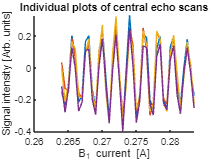

    
        % plotting individual central echo loops
    if plot_individual_loops == 1
        figure()
            hold on
                for i=1:N_loops
                    plot(I_list_echo, new_array(:, central_grad_index, i))
                end
            hold off
            title('Individual plots of central echo scans')
            xlabel('B_{1} current [A]')
            ylabel('Signal intensity [Arb. units]')
    end


    central_echo_mean = mean_data_array(:, central_grad_index);
    central_echo_std = std_data_array(:, central_grad_index);
    central_echo_error = central_echo_std / sqrt(N_loops);
    
        % plotting mean of central echo with errorbars
    figure()
        errorbar(I_list_echo', central_echo_mean, central_echo_error, 'o-')

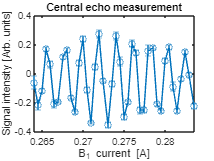

        xlabel('B_{1} current [A]')
        ylabel('Signal intensity [Arb. units]')
        title('Central echo measurement')
        xlim([min(I_list_echo), max(I_list_echo)])

%%% REMOVAL OF CENTRAL FREQUENCIES IN 2D-ARRAY (WORKS!) %%%

    for i=1:N_grad-1
        mean_data_array(:, i) = mean_data_array(:,i) - mean(mean_data_array(:,i));
    end

    for i=1:N_grad-1
        for j=1:N_loops
            new_array(:,i,j) = new_array(:,i,j) - mean(new_array(:,i,j));
        end
    end


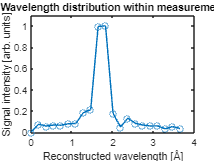

%%% LOCATING HIGH INTENSITY LAMBDA COMPONENTS 

    central_echo_mean = central_echo_mean - mean(central_echo_mean);
    reconstructed_lambda_intensity = abs(fftshift(fft(central_echo_mean)));
    reconstructed_lambda_intensity = reconstructed_lambda_intensity ./ max(reconstructed_lambda_intensity);

%     figure()
%         plot(lambda_list, reconstructed_lambda_intensity, 'o-')
%         yline(selection_threshold)
%         title('Lambda distribution from central echo')

    %% plotting half of the spectum

   figure()
       plot(-1 * lambda_list(1:21)*1e10, reconstructed_lambda_intensity(1:21), 'o-')
       xlabel('Reconstructed wavelength [Å]')
       ylabel('Signal intensity [arb. units]')
       ylim([0, 1.1])
       title('Wavelength distribution within measurement')


    lambda_selected_indexes = [];
    for i=1:length(reconstructed_lambda_intensity)
        if reconstructed_lambda_intensity(i) > selection_threshold
            if i > 20
                lambda_selected_indexes(end+1) = i;
            end
        end
    end

    disp(lambda_selected_indexes)

    30    31



%%% SURF PLOTTING MESH INITIATIONS

    % ECHO MESH LATE INITIATION
    [I_grad_mesh, I_echo_mesh] = meshgrid(I_list_grad, I_list_echo);

    % SPATIAL AND LAMBDA LATE INITIATION
    [x_axis_mesh, lambda_list_mesh] = meshgrid(x_axis, lambda_list);


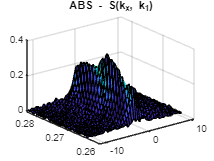

%%% DOUBLE FOURIER TRANSFORM INTO IMAGE & LAMBDA SPACE %%%

figure()
    surf(I_grad_mesh, I_echo_mesh, abs(mean_data_array))
    title('ABS - S(k_{x}, k_{1})')

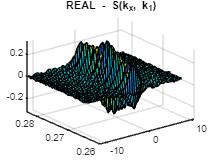

figure()
    surf(I_grad_mesh, I_echo_mesh, real(mean_data_array))
    title('REAL - S(k_{x}, k_{1})')

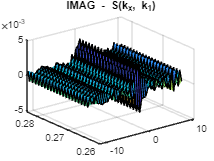

figure()
    surf(I_grad_mesh, I_echo_mesh, imag(mean_data_array))
    title('IMAG - S(k_{x}, k_{1})')

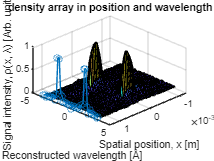


%         complex_mag_A = [];
%     for i=1:(N_grad-1) %%% WAVELENGTH FOURIER TRANSFORM - N_B1 %%%
%         complex_mag_A(:, i) = fftshift(ifft(mean_data_array(:, i)));
%     end

%         complex_mag_B = [];
%     for i=1:(N_lambda-1) %%% SPATIAL FOURIER TRANSFORM - N_grad %%%
%         complex_mag_B(i, :) = fftshift(fft(complex_mag_A(i, :)));
%     end
%     
%     complex_mag_B = complex_mag_B ./ max(max(complex_mag_B)); %array normalise
    complex_mag_A = [];
    for i=1:(N_grad-1)
        for j=1:N_loops
            complex_mag_A(:,i,j) = fftshift(ifft(new_array(:,i,j)));
        end
    end

    complex_mag_B = [];
    for i=1:(N_lambda-1)
        for j=1:N_loops
            complex_mag_B(i,:,j) = fftshift(fft(complex_mag_A(i,:,j)));
        end
    end

    for j=1:N_loops
        complex_mag_B(:,:,j) = complex_mag_B(:,:,j) ./ max(max(complex_mag_B(:,:,j)));
    end

    complex_mag_B(:,:,:) = abs(complex_mag_B(:,:,:));

    complex_mag_B_mean = mean(complex_mag_B, 3);
    complex_mag_B_std = std(complex_mag_B, [], 3);
    complex_mag_B_error = complex_mag_B_std ./ sqrt(N_loops);

%     figure()
%         surf(x_axis_mesh, lambda_list_mesh, abs(complex_mag_B(:,:,1)))
%         title('density array for first loop')
%         xlabel('Spatial position, x [m]')
%         ylabel('Wavelength [m^{-1}]')
%         zlabel('Signal intensity [Arb. units]')

    figure()
        surf(x_axis_mesh, lambda_list_mesh.*1e10, abs(mean(complex_mag_B(:,:,1), 3)) )
        hold on
        xlabel('Spatial position, x [m]')
        ylabel('Reconstructed wavelength [Å]')
        zlabel('Signal intensity, ρ(x, λ) [Arb. units]')
        title('density array in position and wavelength')
        plot3(zeros(40,1)+1.3e-3,lambda_list*1e10, reconstructed_lambda_intensity, 'o-')
        view(45+90, 45)


%plot3(x_axis, zeros(length(x_axis))+5e-10, abs(complex_mag_B_mean(:,25)))
%B1_sideplot = plot3(I_list_echo, zeros(length(I_list_echo))+echo_inset_offset, mean_data_array(:,25) , 'o-' , 'LineWidth', 2.0 , 'Color', 'blue');
%grad_sideplot = plot3(zeros(length(I_list_grad))+grad_inset_offset , I_list_grad , mean_data_array(21,:) , 'o-' , 'LineWidth', 2.0 , 'Color', 'red');

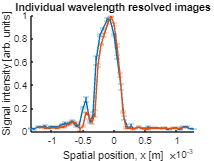

%%% PLOTTING OF HIGH INTENSITY LAMBDA COMPONENTS

    selected_lambda = lambda_list(lambda_selected_indexes);
    selected_velocities = h ./ (m .* selected_lambda);

    grad_max = 11.2019 * 0.133;
    L_encoding = 0.15;

    effective_resolutions = (pi .* selected_velocities) / (L_encoding*gamma*grad_max);

    x_axis_rescale = [];
    for i=1:length(effective_resolutions)
        x_axis_rescale(:, i) = linspace(-(N_grad-1)/2, (((N_grad-1)/2)-1), N_grad-1) .* effective_resolutions(i);
    end

    %%% CALCULATES THE UNCERTAINTY FOR EACH LAMBDA PLOT

    high_intensity_lambda_spectra = [];
    high_intensity_lambda_spectra_error = [];
    for i=1:length(effective_resolutions)
        high_intensity_lambda_spectra(:,end+1) = complex_mag_B_mean(lambda_selected_indexes(i), :);
        high_intensity_lambda_spectra_error(:, end+1) = complex_mag_B_error(lambda_selected_indexes(i), :);
    end

    figure()
        hold on
        for i=1:length(effective_resolutions)
            errorbar(x_axis_rescale(:,i), high_intensity_lambda_spectra(:,i), high_intensity_lambda_spectra_error(:,i))
        end
        title('Individual wavelength resolved images')
        xlabel('Spatial position, x [m]')
        ylabel('Signal intensity [arb. units]')
        hold off


    signals_for_each_image = [];
    signals_for_each_image(:, :, :) = new_array(lambda_selected_indexes, :, :);
    mean_signals_for_each_image = mean(signals_for_each_image, 3);
    std_signals_for_each_image = std(signals_for_each_image, [], 3) ./ sqrt(N_loops);

    %%% PLOTTING OF THE VELCOITY SELECTED S(kx) SPECTRA
    
    velocity_legend = []


velocity_legend =

     []



    for i=1:length(lambda_selected_indexes)
        velocity_legend{i} = [strcat(num2str(selected_velocities(i)), 'ms^{-1}')];
    end

    axis_shift_factor = effective_resolutions ./ max(effective_resolutions);
%     figure()
%         hold on
%         for i=1:length(lambda_selected_indexes)
%             errorbar(I_list_grad * axis_shift_factor(i), abs(mean_signals_for_each_image(i,:)), std_signals_for_each_image(i,:))
%         end
%         legend(velocity_legend, 'Interpreter', 'none')
%         hold off
% 
%     figure()
%         hold on
%         for i=1:length(lambda_selected_indexes)
%             errorbar(I_list_grad, abs(mean_signals_for_each_image(i,:)), std_signals_for_each_image(i,:))
%         end
%         legend(velocity_legend, 'Interpreter', 'none')
%         hold off

%     test_images = []
%     for i=1:length(lambda_selected_indexes)
%         test_images(:, end+1) = abs(fftshift(fft(mean_signals_for_each_image(i,:))));
%     end

%     figure()
%         hold on
%         for i=1:length(lambda_selected_indexes)
%             plot(test_images(:,i))
%         end
%         hold off

%     for i=lambda_selected_indexes
%         for j=1:N_loops
%         signals_for_each_image(i, :, j) = new_array(i, :, j)
%         end
%     end
%     figure()
%         plot(signals_for_echo_image)
    


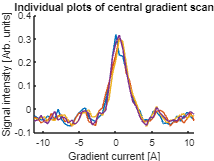

%%% CENTRAL GRADIENT SCAN MEASUREMENT WITH ERROR %%%
    
    if plot_individual_loops == 1
        figure()
            hold on
                for i=1:N_loops
                    plot(I_list_grad, new_array(central_echo_index,:,i) - mean(new_array(central_echo_index,:,i)))
                end
            hold off
            title('Individual plots of central gradient scan')
            xlabel('Gradient current [A]')
            ylabel('Signal intensity [Arb. units]')
    end


    central_gradient_scan = mean_data_array(central_echo_index, :);
    central_gradient_std = std_data_array(central_echo_index, :);
    central_gradient_error = central_gradient_std / sqrt(N_loops);

    figure()
        errorbar(I_list_grad', central_gradient_scan, central_gradient_error(1:end-1), 'o-')

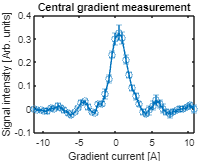

        xlabel('Gradient current [A]')
        ylabel('Signal intensity [Arb. units]')
        title('Central gradient measurement')

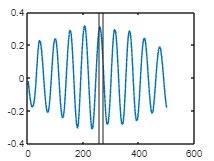

%%% FINDING SINGLE SCAN USING IMAG COMPONENT INTERPOLATION

    N_echo_interp = 501;
    interp_I_echo_list = linspace(min(I_list_echo), max(I_list_echo), N_echo_interp);
    mean_interp_central_echo = interp1(I_list_echo, central_echo_mean, interp_I_echo_list, 'spline');

    real_index = 259; % with N_interp = 501
    imag_index = 273; % with N_interp = 501

%     figure()
%         plot(interp_I_echo_list, real(mean_interp_central_echo))
%         hold on
%         plot(interp_I_echo_list, imag(mean_interp_central_echo))
%         hold off

    figure()
        plot(real(mean_interp_central_echo))
        hold on
        xline(real_index)
        xline(imag_index)
        hold off

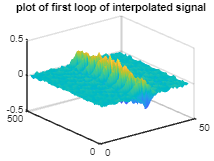

    
    interp_new_array = [];
        % GENERATES NEW INTERPOLATED ARRAY
    for i=1:(N_grad-1)
        for j=1:N_loops
            interp_new_array(:,i,j) = interp1(I_list_echo, new_array(:,i,j), interp_I_echo_list);
        end
    end
  
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% !!!!!
    %% CAREFUL, THIS COMMAND MIGHT NOT BE A GREAT IDEA (THROWING AWAY THE IMAGINARY COMP)
    interp_new_array = real(interp_new_array);
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% !!!!!

    figure()
        surf(real(interp_new_array(:,:,1)))
        title('plot of first loop of interpolated signal')
        shading flat

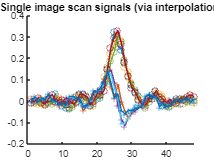


    for i=1:N_loops
        complex_data(:, i) = interp_new_array(real_index, :, i) + (1i * interp_new_array(imag_index, :, i));
    end

    figure()
    hold on
        for i=1:N_loops
            plot(real(complex_data(:,i)), 'o-')
            plot(imag(complex_data(:,i)), '+-')
        end
        title('Single image scan signals (via interpolation)')
    hold off

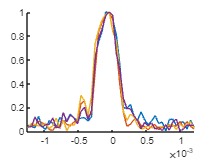


    single_scan_spatial_spectra = [];
    for i=1:N_loops 
        single_scan_spatial_spectra(:, end+1) = abs(fftshift(fft(complex_data(:,i))));
        single_scan_spatial_spectra(:,i) = single_scan_spatial_spectra(:,i) ./ max(single_scan_spatial_spectra(:,i)); %norm
    end

    figure()
    hold on
    for i=1:N_loops
        plot(x_axis, single_scan_spatial_spectra(:,i))
    end
    hold off

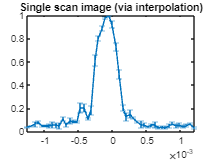

    
    single_scan_spatial_spectra_mean = mean(single_scan_spatial_spectra, 2);
    single_scan_spatial_spectra_std = std(single_scan_spatial_spectra, [], 2);
    single_scan_spatial_spectra_error = single_scan_spatial_spectra_std ./ sqrt(N_loops);

    figure()
        errorbar(x_axis, single_scan_spatial_spectra_mean, single_scan_spatial_spectra_error)
        title('Single scan image (via interpolation)')

%%% BRIEF SNR CHECKS

    single_image_mean_error = mean(single_scan_spatial_spectra_error);
    high_intensity_lambda_mean_error = mean(high_intensity_lambda_spectra_error,1);
    SNR_factor = single_image_mean_error ./ max(high_intensity_lambda_mean_error);


%%% HIGH QUALITY OVERLAYED SURF PLOT OF SIGNAL %%%
    
    [I_grad_mesh, I_echo_mesh] = meshgrid(I_list_grad, I_list_echo);
    
    figure(); surf(I_echo_mesh, I_grad_mesh, real(mean_data_array));
    xlabel('Applied B_{1} current [A]'); ylabel('Applied gradient current [A]');
    zlabel('Signal Intensity [Arb. units]');
    view(45, 45); colormap('jet'); alpha 0.8;
    xh = get(gca, 'XLabel'); posx = get(xh, 'Position');
    yh = get(gca, 'YLabel'); posy = get(yh, 'Position');
    set(xh, 'Position', posx.*[1,1,1], 'Rotation', -27);
    set(yh, 'Position', posy.*[1,0.5,1], 'Rotation', 27);
    
    % defines position of inset plots
    echo_inset_offset = -12;
    grad_inset_offset = 0.285;
    
    hold on
    B1_sideplot = plot3(I_list_echo, zeros(length(I_list_echo))+echo_inset_offset, mean_data_array(:,25) , 'o-' , 'LineWidth', 2.0 , 'Color', 'blue');

    grad_sideplot = plot3(zeros(length(I_list_grad))+grad_inset_offset , I_list_grad , mean_data_array(21,:) , 'o-' , 'LineWidth', 2.0 , 'Color', 'red');

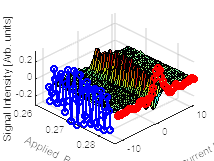

    hold off

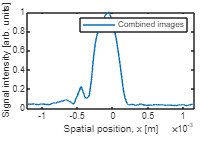

%%% INTERPOLATION AND HIGH INTENSITY LAMBDA COMBINATION %%%

    interp_disc_factor = 50; % integer number of x * N_grad data points
    interp_axis = linspace(-FOV/2, FOV/2, N_grad*interp_disc_factor);
    interp_intensity = [];
    
    % MANUAL RE
%     lambda_selected_indexes = [30, 31]

    for i=1:length(lambda_selected_indexes);
        interp_intensity(:, end+1) = interp1(x_axis_rescale(:,i) , abs(mean(complex_mag_B(lambda_selected_indexes(i),:, :), 3)), interp_axis, 'linear');
    end


%     disp(interp_intensity)
    summed_image = sum(interp_intensity, 2); % sum all bins over lambdas
    summed_image = summed_image ./ max(summed_image); % normalise the summed image

        subplot(4,4,[1:12])
        plot(interp_axis, summed_image ./ max(summed_image))
%         hold on
%         plot(positions_reconstructed, fft_single_recon ./ max(fft_single_recon));
%         hold off
        xlabel('Spatial position, x [m]');
        ylabel('Signal intensity [arb. units]');
        legend('Combined images', 'B_{1}=B_{2} (Single image)');

%     test_density_signal = fft2(mean_data_array)
%     figure()
%         surf(abs(fftshift(test_density_signal ./ max(max(test_density_signal)))))
%         title('2D FFT applied to original dataset test')
